%% set signal parameters
xlen = 256; ylen = 256;
fx = 100; fy = 110;
xdelay = 5; ydelay = 0;

%% generate each sin wave
x = [zeros(1, xdelay) sin(2 * pi * fx * (0:(xlen-1)) / xlen)];
y = [zeros(1, ydelay) sin(2 * pi * fy * (0:(ylen-1)) / ylen)];

%% conduct Dynamic Pattern Matching
[dist, map, g] = dpMatch(x, y, 10, 50, 0.6);

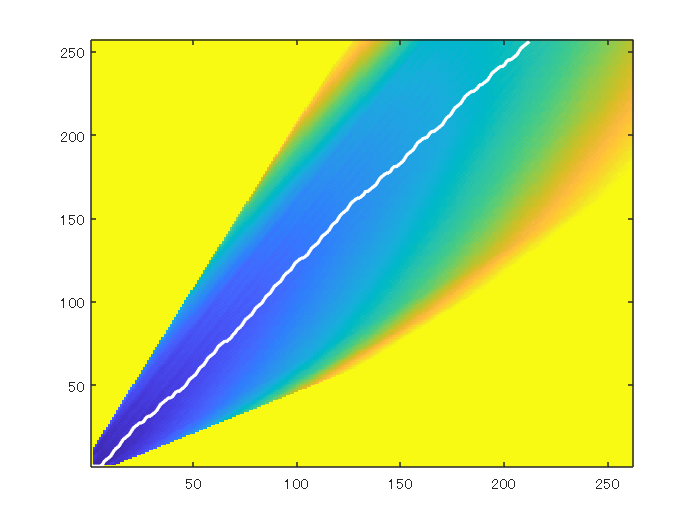

%% plot results
imagesc(min(g', 100)); axis xy; hold on;
plot(map, 'w', 'LineWidth', 2);

%% conduct Dynamic Pattern Matching
[dist, map, g] = dpMatch(x, y, 0, 0, 0.6);

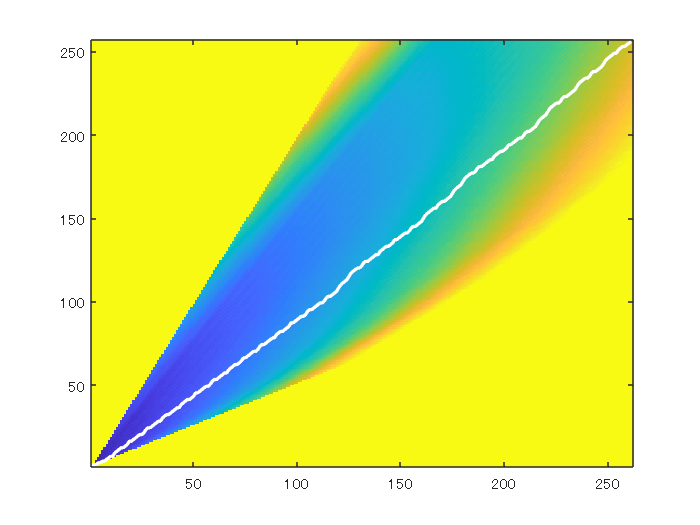

%% plot results
imagesc(min(g', 100)); axis xy; hold on;
plot(map, 'w', 'LineWidth', 2);

xdelay = 50; ydelay = 0;

%% generate each sin wave
x = [zeros(1, xdelay) sin(2 * pi * fx * (0:(xlen-1)) / xlen)];
y = [zeros(1, ydelay) sin(2 * pi * fy * (0:(ylen-1)) / ylen)];

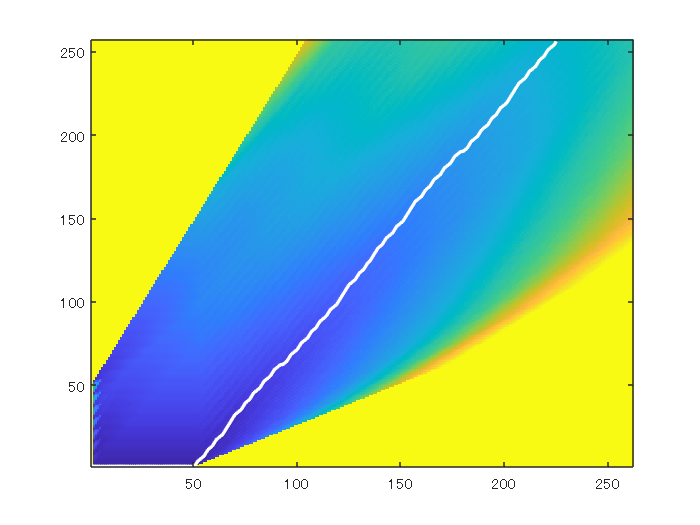

%% conduct Dynamic Pattern Matching
[dist, map, g] = dpMatch(x, y, 50, 100, 0.6);

%% plot results
imagesc(min(g', 100)); axis xy; hold on;
plot(map, 'w', 'LineWidth', 2);

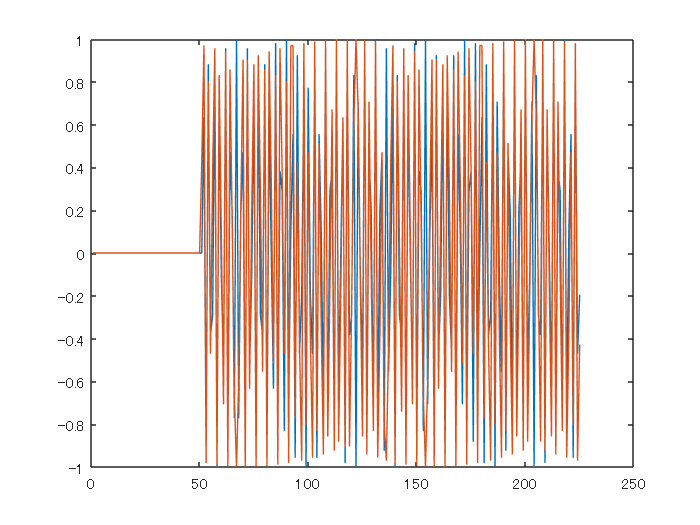

figure;
plot(1:length(map), x(1:length(map)), 1:length(map), y(map));